# SAMPLE OF THE USE OF class_soil_GSD 

## INPUTS:

Grain Size Distribution:

%       Particle Diameter       Aggregated Particle Volume passing
%       [m]                     [m3·m-3]
GSD = [ 0                       ,0;...
        2.00000000000000e-06    ,0.0200000000000000;...
        5.00000000000000e-05    ,0.130000000000000;...
        0.000106000000000000    ,0.256000000000000;...
        0.000250000000000000    ,0.743000000000000;...
        0.000500000000000000    ,0.916000000000000;...
        0.00100000000000000     ,0.985000000000000;...
        0.00200000000000000     ,0.997000000000000];

Porosity:

npor = 0.45;    

D_max (optional) maximum diameter for 100%:

Dg_max = nan; 

## CONSTRUCTION OF THE INSTANCE OF THE AP81 MODEL:

soil = class_soil_GSD(...
    'GSD',GSD,...
    'npor',npor,...
    'Dg_max',Dg_max);

## EXAMPLES OF POSSIBLE OUTPUTS OF THE MODEL:

Grain Size in the GSD at 20% (D20) in [m]: 

disp(soil.Dg_FVg_from_GSD(0.2));

   8.2051e-05



Cummulated grain volume per unit given grain size:

disp(soil.Dg_FVg_from_GSD(0.2));

disp(soil.FVg_Dg_from_GSD(0.00065));

    0.9514



## PLOT OF THE PORE SIZE DISTRIBUTION:

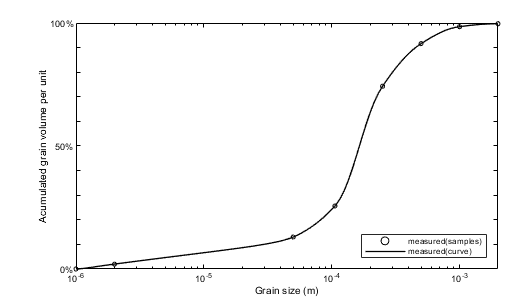

soilplot = class_soil_GSD_PLOT(soil);
soilplot = soilplot.show_GSD('Pore Size Distribution (PSD)');
%soilplot = soilplot.add_PSD_from_GSD(soil,'--',1,[0,0,0]);
%legend({'measured(samples)','measured(curve)','predicted'},'Location','Southeast');
legend({'measured(samples)','measured(curve)'},'Location','Southeast');

clear('D_max','GSD','npor');
